f = @(x) x.*sin(x) - cos(x);

eps = 10^-13

eps =      1.000000000000000e-13


delta = 10^-14

delta =      1.000000000000000e-14


h = 10^-10;
iter = 10;

x1 = 0;
x2 = 4*pi;
x = linspace(x1, x2, (x2-x1)/0.1);
y = f(x);

plot(x, y);
hold on;

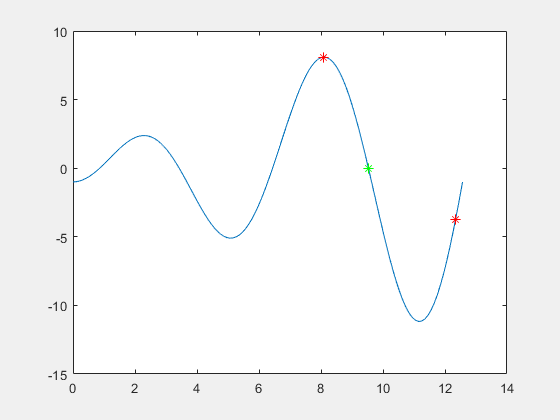

p1 = ginput(1);
plot(p1(1), f(p1(1)), 'r*', 'MarkerSize', 7);
p2 = ginput(1);
plot(p2(1), f(p2(1)), 'r*', 'MarkerSize', 7);
if p1(1)>p2(1)
    p3 = p1;
    p1 = p2;
    p2 = p3;
end

df = derivative(f);
x_ = (p1(1) + p2(1))/2;
[xr, yr] = fzero(f, x_);
x_cur = x_ - f(x_)/df(x_);

for i = 1:iter
    x_cur_ = x_cur - f(x_cur)/df(x_cur);
    x_cur = x_cur_;
    
    if x_cur < p1(1) || x_cur > p2(1)
        error("Корня нет");
        break;
    end
    if abs(f(x_cur)) < eps
        break;
    end
end

plot(x_cur, f(x_cur), 'g*', 'MarkerSize', 7);


format long;
a = abs(xr-x_cur);
fprintf('Верный корень: %.16f', xr)

Верный корень: 9.5293344053619631

fprintf('Найденный корень: %.16f', x_cur)

Найденный корень: 9.5293344053619631

fprintf('Абсолютная погрешность: %e', a)

Абсолютная погрешность: 0.000000e+00



function ans = derivative(f)
    h = 10^-10;
    func = @(x) (f(x+h)-f(x))/h;
    ans = func;
end

